%Quintic Trajectory Generation
%Points
P0=[0 ;0;0];P1=[0 ;0 ;1];P2=[1;0;1];
P3=[1;1;1];P4=[0;1;1];P5=[0;0;1];
%Calc Coefficents - P1-5 have the same A mat, P01 has different A mat
t0 = 0;
tfP01 = 5;
tf = 15;
trajec_one = [];
trajec_two = [];
trajec_three = [];
trajec_four = [];
trajec_five = [];


trajPoint1 = calcTraj(t0,tfP01,P0,P1)

b =          0         0         0
         0         0         0
         0         0         0
         0         0    0.0800
         0         0   -0.0240
         0         0    0.0019


$$trajPoint1 = \left[\begin{array}{ccc} 0 & 0 & \frac{2\,{\mathrm{currT}}^{3}}{25}-\frac{3\,{\mathrm{currT}}^{4}}{125}+\frac{6\,{\mathrm{currT}}^{5}}{3125} \end{array}\right]$$

tfP01 = 15

tfP01 = 15

trajPoint2 = calcTraj(t0,tfP01,P1,P2)

b =          0         0    1.0000
         0         0         0
         0         0         0
    0.0030         0         0
   -0.0003         0         0
    0.0000         0         0


$$trajPoint2 = \left[\begin{array}{ccc} \frac{2\,{\mathrm{currT}}^{3}}{675}-\frac{{\mathrm{currT}}^{4}}{3375}+\frac{4664065662093477\,{\mathrm{currT}}^{5}}{590295810358705651712} & 0 & 1 \end{array}\right]$$

trajPoint3 = calcTraj(t0,tfP01,P2,P3)

b =     1.0000         0    1.0000
         0         0         0
         0         0         0
         0    0.0030         0
         0   -0.0003         0
         0    0.0000         0


$$trajPoint3 = \left[\begin{array}{ccc} 1 & \frac{2\,{\mathrm{currT}}^{3}}{675}-\frac{{\mathrm{currT}}^{4}}{3375}+\frac{4664065662093477\,{\mathrm{currT}}^{5}}{590295810358705651712} & 1 \end{array}\right]$$

trajPoint4 = calcTraj(t0,tfP01,P3,P4)

b =     1.0000    1.0000    1.0000
         0         0         0
         0         0         0
   -0.0030         0         0
    0.0003         0         0
   -0.0000         0         0


$$trajPoint4 = \left[\begin{array}{ccc} 1-\frac{2\,{\mathrm{currT}}^{3}}{675}+\frac{{\mathrm{currT}}^{4}}{3375}-\frac{4664065662093477\,{\mathrm{currT}}^{5}}{590295810358705651712} & 1 & 1 \end{array}\right]$$

trajPoint5 = calcTraj(t0,tfP01,P4,P5)

b =          0    1.0000    1.0000
         0         0         0
         0         0         0
         0   -0.0030         0
         0    0.0003         0
         0   -0.0000         0


$$trajPoint5 = \left[\begin{array}{ccc} 0 & 1-\frac{2\,{\mathrm{currT}}^{3}}{675}+\frac{{\mathrm{currT}}^{4}}{3375}-\frac{4664065662093477\,{\mathrm{currT}}^{5}}{590295810358705651712} & 1 \end{array}\right]$$



t1 = 0:0.5:5;

t1 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


t2 = 0:0.5:15;

t2 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000


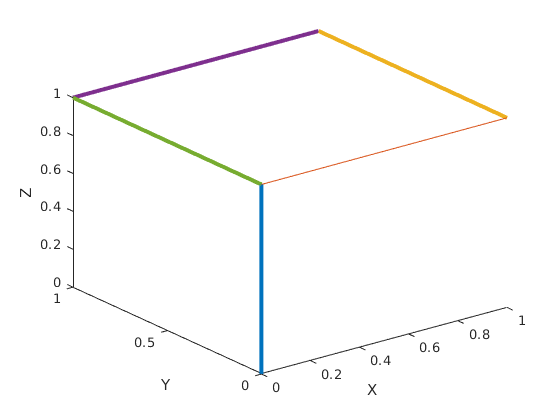


for i = 1:length(t1)
    traj_one = [0, 0, 6*t1(i)^5/3125 - 3*t1(i)^4/125 + 2*t1(i)^3/25];
    trajec_one = [trajec_one;traj_one];
end

for i = 1:length(t2)

    traj_two = [4664065662093477*t2(i)^5/590295810358705651712 - t2(i)^4/3375 + (2*t2(i)^3)/675, 0, 1];
    trajec_two = [trajec_two;traj_two];

    traj_three   = [1, 4664065662093477*t2(i)^5/590295810358705651712 - t2(i)^4/3375 + 2*t2(i)^3/675, 1];
    trajec_three = [trajec_three;traj_three];

    traj_four =  [- (4664065662093477*t2(i)^5)/590295810358705651712 + t2(i)^4/3375 - (2*t2(i)^3)/675 + 1, 1, 1];
    trajec_four = [trajec_four;traj_four];

    traj_five = [0, - (4664065662093477*t2(i)^5)/590295810358705651712 + t2(i)^4/3375 - (2*t2(i)^3)/675 + 1, 1];
    trajec_five = [trajec_five; traj_five];
end
%plot(t2,trajec_five)
p = plot3(trajec_one(:,1),trajec_one(:,2),trajec_one(:,3));
p.LineWidth = 3;
hold on;
plot3(trajec_two(:,1),trajec_two(:,2),trajec_two(:,3));
p.LineWidth = 3;

p = plot3(trajec_three(:,1),trajec_three(:,2),trajec_three(:,3));
p.LineWidth = 3;

p = plot3(trajec_four(:,1),trajec_four(:,2),trajec_four(:,3));
p.LineWidth = 3;

x = plot3(trajec_five(:,1),trajec_five(:,2),trajec_five(:,3));
x.LineWidth = 3;
xlabel('X')
ylabel('Y')
zlabel('Z')
hold off;

function ret = calcTraj(t0,tf,P0,PF)
    syms currT
    Amat = [1 t0 t0^2 t0^3 t0^4 t0^5;
        0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
        0 0 2 6*t0 12*t0^2 20*t0^3;
        1 tf tf^2 tf^3 tf^4 tf^5;
        0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
        0 0 2 6*tf 12*tf^2 20*tf^3];
    
    b = [inv(Amat)*[P0(1);0;0;PF(1);0;0], inv(Amat)*[P0(2);0;0;PF(2);0;0], inv(Amat)*[P0(3);0;0;PF(3);0;0]]

    A = [1 currT currT^2 currT^3 currT^4 currT^5];

    ret = A*b;
end